Задание 1. Кластеризация соц. сети.

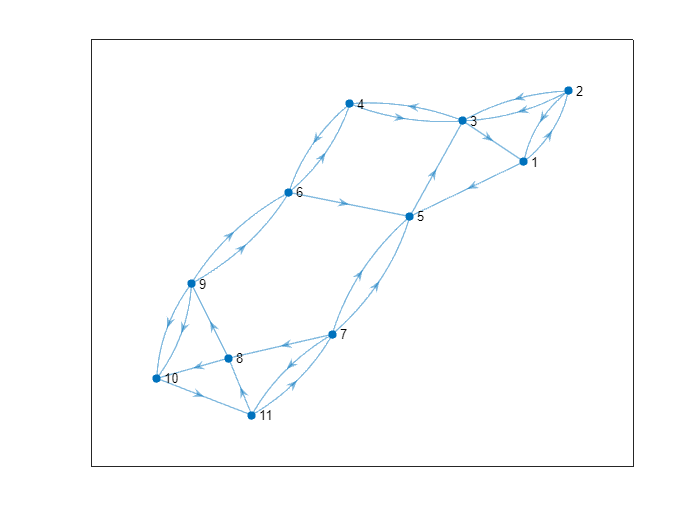

% Начальный граф
s = [1 1 2 2 2 3 3 4 4 5 6 6 7 7 7 7  8 8  9 9 9  9  10 11 11];
t = [2 5 1 3 3 1 4 3 6 3 4 5 5 5 8 11 9 10 6 6 10 10 11 7  8];
G = digraph(s,t);
g0 = plot(G);
hold off

M = [
  0	1/3	1/2	  0	0	  0	  0	  0	  0	0	  0
1/2	  0	  0	  0	0	  0	  0	  0	  0	0	  0
  0	2/3	  0	1/2	1	  0	  0	  0	  0	0	  0
  0	  0	1/2	  0	0	1/2	  0	  0	  0	0	  0
1/2	  0	  0	  0	0	1/2	1/2	  0	  0	0	  0
  0	  0	  0	1/2	0	  0	  0	  0	1/2	0	  0
  0	  0	  0	  0	0	  0	  0	  0	  0	0	1/2
  0	  0	  0	  0	0	  0	1/4	  0	  0	0	1/2
  0	  0	  0	  0	0	  0	  0	1/2	  0	0	  0
  0	  0	  0	  0	0	  0	  0	1/2	1/2	0	  0
  0	  0	  0	  0	0	  0	1/4	  0	  0	1	  0];

d=1; % Коэффициент затухания
delta = ones(N,1); 
N = 11;
V = ones(N,1)/N; % Начальное значенрие вектора важности
M = (d * M + (1 - d) / N); % Нулевая итерация
% Цикл реализации алгоритма:
while not(isequal(delta, zeros(N,1)))
    V_last = V;
    V = M * V_last;
    delta = abs(V_last-V);
end
V

V =     0.1782
    0.0891
    0.2970
    0.1980
    0.1386
    0.0990
         0
         0
         0
         0
